clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


n = param.n;
Cy = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);

listOfUncertainties = {[-.8,.8]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end

% Step 1-3
yalmip('clear')
q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q = blkdiag(q{:});
Y = blkdiag(y{:});

% Setup constraint
param.ctrl.Ks = control.DesignProcedureRealUncertainties(param,0,listOfUncertainties);

Evaluation of design procedure for real uncertainties 
Q is positive definite


ans =     0.1170    0.1172    0.1176    0.1181    0.3900    0.3917    0.3928    0.3931    2.0935    2.0954    2.0965    2.0968


Eigenvalues of the decoupled systems are all negative 


ans =   -4.3935 + 0.0000i  -0.5804 + 0.1915i  -0.5804 - 0.1915i  -4.4156 + 0.0000i  -0.5696 + 0.2122i  -0.5696 - 0.2122i  -4.3771 + 0.0000i  -0.5706 + 0.2112i  -0.5706 - 0.2112i  -4.3996 + 0.0000i  -0.5889 + 0.1837i  -0.5889 - 0.1837i


Eigenvalues of the coupled systems are all negative 


ans =    -4.8537   -5.2529   -5.3511   -5.4057   -1.3979   -1.7602   -1.8207   -1.8679   -0.4229   -0.3965   -0.3937   -0.3917


ans = ans(:,:,1) =

   10.1260   -1.5635    3.6628


ans(:,:,2) =

    9.2525   -1.4116    3.3797


ans(:,:,3) =

    9.0547   -1.3602    3.3122


ans(:,:,4) =

    9.9257   -1.5165    3.6081


% constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
% for i=1:length(Uncertainties)
%     constraints = [constraints, param.model.A * Q + Q * param.model.A.' + param.model.B * (eye(m) + Uncertainties(i)) * Y + Y.' * (eye(m) + Uncertainties(i))' * param.model.B.' <= 0];
% end
% constraints = [constraints,  Q >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, [], options)

% constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
% for i=1:length(Uncertainties)
%     constraints = [constraints, param.model.A * Q + Q * param.model.A.' + param.model.B * (eye(m) + Uncertainties(i)) * Y + Y.' * (eye(m) + Uncertainties(i))' * param.model.B.' <= 0];
% end
% constraints = [constraints,  Q - eye(12) >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, trace(Q), options)

% step 4
K = value(Y)/value(Q);
Ksf = K

Ksf =    10.1260   -1.5635    3.6628         0         0         0         0         0         0         0         0         0
         0         0         0    9.2525   -1.4116    3.3797         0         0         0         0         0         0
         0         0         0         0         0         0    9.0547   -1.3602    3.3122         0         0         0
         0         0         0         0         0         0         0         0         0    9.9257   -1.5165    3.6081



%step 5
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag(p{:});
sigma = sdpvar(1);
constraints = [param.model.A.'*P + P*param.model.A - sigma*(Cy.'*Cy) <= 0];
for i=1:length(Uncertainties)
    constraints = [constraints, (param.model.A + param.model.B*(eye(m) + Uncertainties(i))*K).'*P + P*(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*K)<=0];
end
constraints = [constraints, P>=eye(12), sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0627
       solvertime: 0.0053
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


P_min = value(P)

P_min =     9.0024   -1.1491    2.4803         0         0         0         0         0         0         0         0         0
   -1.1491    3.1561    0.9808         0         0         0         0         0         0         0         0         0
    2.4803    0.9808    5.0664         0         0         0         0         0         0         0         0         0
         0         0         0    8.5913   -1.1318    2.3596         0         0         0         0         0         0
         0         0         0   -1.1318    3.1144    0.9441         0         0         0         0         0         0
         0         0         0    2.3596    0.9441    4.9213         0         0         0         0         0         0
         0         0         0         0         0         0    8.4230   -1.1318    2.3013         0         0         0
         0         0         0         0         0         0   -1.1318    3.1275    0.9246         0         0         0
         0         0    


% Step 6
yalmip('clear')
f = cell(1,param.n);
for j=1:param.n
    f{j} = sdpvar(1,2,'full');
end
F = blkdiag(f{:});
gamma = sdpvar(1);

k = [F(:,1);F(:,2);F(:,3);F(:,4);F(:,5);F(:,6);F(:,7);F(:,8)];
constraints = [gamma, k.'; k, eye(size(k,1))]>=0;

for i=1:length(Uncertainties)
    if (eye(m) + Uncertainties(i)) ~= 0 % In case the uncertainties is 0 and the sdpvar is missing
        constraints = [constraints, [(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*F*Cy).'*P_min + P_min*(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*F*Cy)]<=0];
    else
        % the sdpvar is missing, calculate the definitness
        try chol(-(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*F*Cy).'*P_min + P_min*(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*F*Cy));
            disp('Matrix is symmetric negative definite.')
        catch ME
            disp('Matrix is not symmetric negative definite')
        end
    end
end

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0681
       solvertime: 0.0059
             info: 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (MOSEK-SDP)'
          problem: 1


F_min = value(F)

F_min = 1.0e-12 *

    0.3904    0.1425         0         0         0         0         0         0
         0         0    0.3631    0.1360         0         0         0         0
         0         0         0         0    0.3522    0.1321         0         0
         0         0         0         0         0         0    0.3830    0.1418


value(gamma)

ans = 1.2983

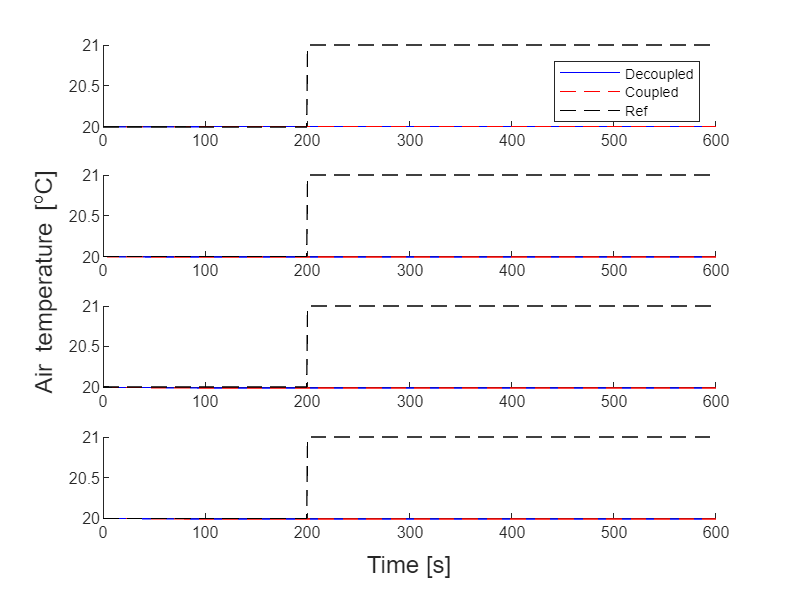


Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = F_min(j,2*(j-1)+1:2*j);
end
param.ctrl.Ks = Ks;


[decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);



% K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.  ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
K = blkdiag(param.ctrl.Ks(1,2:3,1),param.ctrl.Ks(1,2:3,2),param.ctrl.Ks(1,2:3,3),param.ctrl.Ks(1,2:3,4));

s = tf('s');
M = K * Cy/(s * eye(12) - (param.model.A + param.model.B * K * Cy) )*param.model.B;
hinfnorm(M)

ans = 1.0030


M2 = Ksf/(s * eye(12) - (param.model.A + param.model.B * Ksf) )*param.model.B;
hinfnorm(M2)

ans = 1.0937